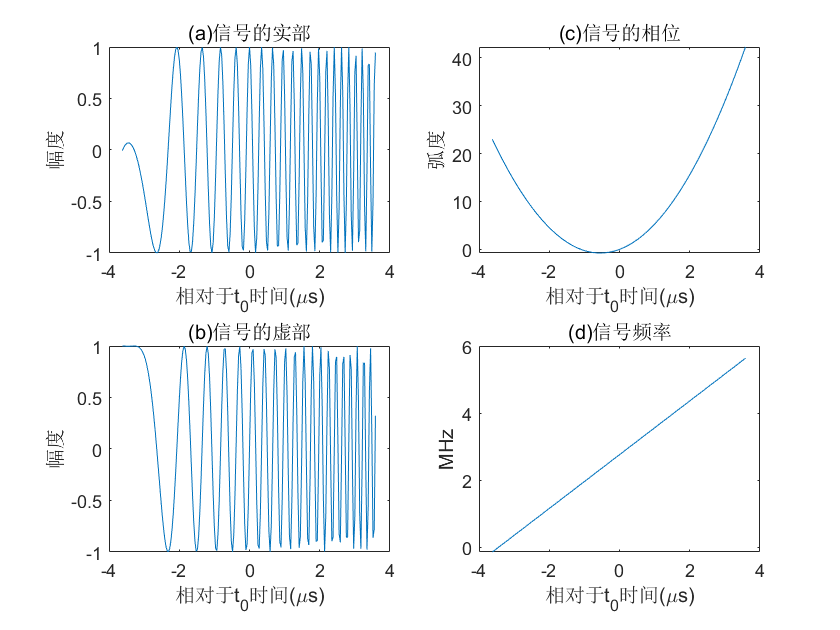

close all;clear all;clc

C = 3e8;                    % 光速
fc = 2.7619e6;              % 中心频率 fc = 20/N*Fs=2.7619e6;
T = 7.24e-6;                % 信号持续时间
B = 5.8e6;                  % 信号带宽
K = B/T;                    % 调频率
ratio = 5;                  % 过采样率
Fs = ratio*B;               % 采样频率
dt = 1/Fs;                  % 采样间隔
N = ceil(T/dt);             % 采样点数
t = ((0:N-1)-N/2)/N*T;      % 时间轴
f = ((0:N-1)-N/2)/N*Fs;     % 频率轴
st1 = exp(1i*2*pi*(fc*t+1/2*K*t.^2));     % 生成信号
st2 = exp(1i*pi*K*t.^2);     % 生成信号

figure,set(gcf,'Color','w');
subplot(2,2,1),plot(t*1e6,real(st1));
title('(a)信号的实部'),xlabel('相对于t_{0}时间(\mus)'),ylabel('幅度');
subplot(2,2,2),plot(t*1e6,fc*t+pi*K*t.^2);
title('(c)信号的相位'),xlabel('相对于t_{0}时间(\mus)'),ylabel('弧度');
subplot(2,2,3),plot(t*1e6,imag(st1));
title('(b)信号的虚部'),xlabel('相对于t_{0}时间(\mus)'),ylabel('幅度');
subplot(2,2,4),plot(t*1e6,(fc+K*t)*1e-6);
title('(d)信号频率'),xlabel('相对于t_{0}时间(\mus)'),ylabel('MHz');

## 中心频率对频谱的影响

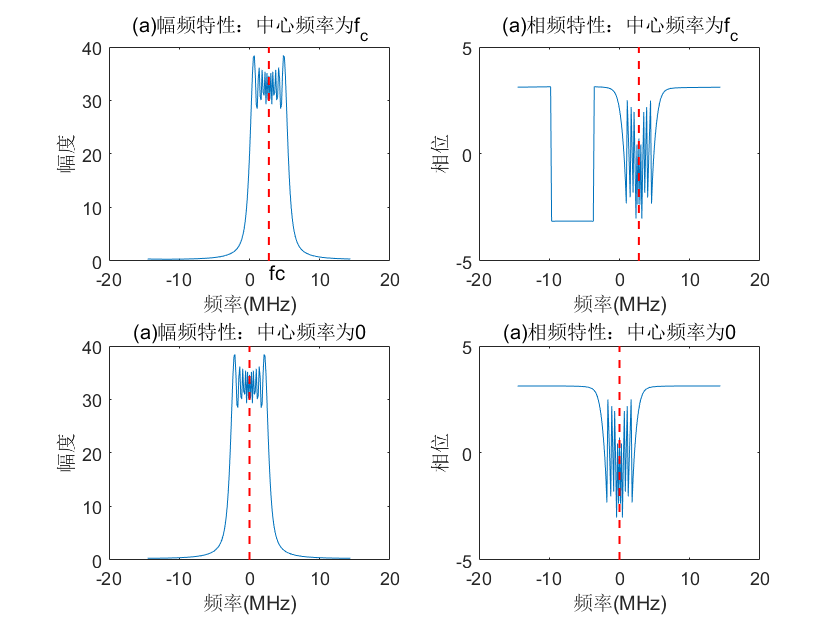

sf1 = fftshift(fft(st1,[],2),2);           % 对st1做傅里叶变换并将零频搬移至中心 
sf2 = fftshift(fft(st2,[],2),2);

figure,set(gcf,'Color','w');
subplot(2,2,1),plot(f*1e-6,abs(sf1));
line([fc*1e-6,fc*1e-6],[0 40],'linestyle','--','Color','r', 'LineWidth', 1);
text(fc*1e-6,-2,'fc')
title('(a)幅频特性：中心频率为f_{c}'),xlabel('频率(MHz)'),ylabel('幅度');
subplot(2,2,2),plot(f*1e-6,angle(sf1));
line([fc*1e-6,fc*1e-6],[-5 5],'linestyle','--','Color','r', 'LineWidth', 1);
title('(a)相频特性：中心频率为f_{c}'),xlabel('频率(MHz)'),ylabel('相位');
subplot(2,2,3),plot(f*1e-6,abs(sf2));
line([0,0],[0 40],'linestyle','--','Color','r', 'LineWidth', 1);
title('(a)幅频特性：中心频率为0'),xlabel('频率(MHz)'),ylabel('幅度');
subplot(2,2,4),plot(f*1e-6,angle(sf2));
line([0,0],[-5 5],'linestyle','--','Color','r', 'LineWidth', 1);
title('(a)相频特性：中心频率为0'),xlabel('频率(MHz)'),ylabel('相位');

## 时移对频谱的影响

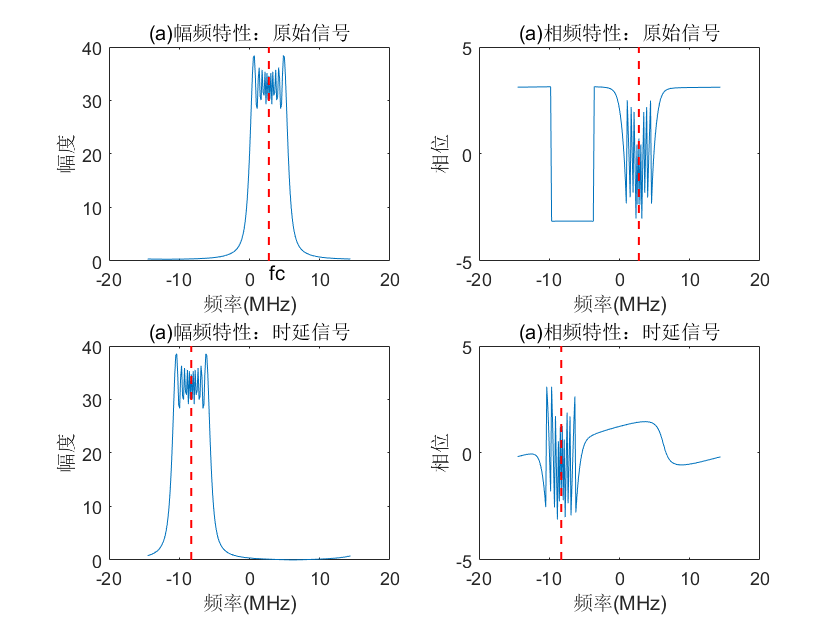

tau =2500/N*T;                                        % 时延tau=3.4476 us
fc_tau = fc-K*tau+(ceil((fc-K*tau)/(-Fs)-1/2))*Fs;     % 时延后的中心频率

st3 = exp(1i*2*pi*(fc*t+1/2*K*t.^2));                 % 原始信号                                                                        
st4 = exp(1i*2*pi*(fc*(t-tau)+1/2*K*(t-tau).^2));     % 时延信号

sf3 = fftshift(fft(st3,[],2),2);
sf4 = fftshift(fft(st4,[],2),2);

figure,set(gcf,'Color','w');
subplot(2,2,1),plot(f*1e-6,abs(sf3));
line([fc*1e-6,fc*1e-6],[0 40],'linestyle','--','Color','r', 'LineWidth', 1);
text(fc*1e-6,-2,'fc')
title('(a)幅频特性：原始信号'),xlabel('频率(MHz)'),ylabel('幅度');
subplot(2,2,2),plot(f*1e-6,angle(sf3));
line([fc*1e-6,fc*1e-6],[-5 5],'linestyle','--','Color','r', 'LineWidth', 1);
title('(a)相频特性：原始信号'),xlabel('频率(MHz)'),ylabel('相位');
subplot(2,2,3),plot(f*1e-6,abs(sf4));
line([fc_tau*1e-6,fc_tau*1e-6],[0 40],'linestyle','--','Color','r', 'LineWidth', 1);
title('(a)幅频特性：时延信号'),xlabel('频率(MHz)'),ylabel('幅度');
subplot(2,2,4),plot(f*1e-6,angle(sf4));
line([(fc_tau)*1e-6,fc_tau*1e-6],[-5 5],'linestyle','--','Color','r', 'LineWidth', 1);
title('(a)相频特性：时延信号'),xlabel('频率(MHz)'),ylabel('相位');

## 解调对频谱的影响

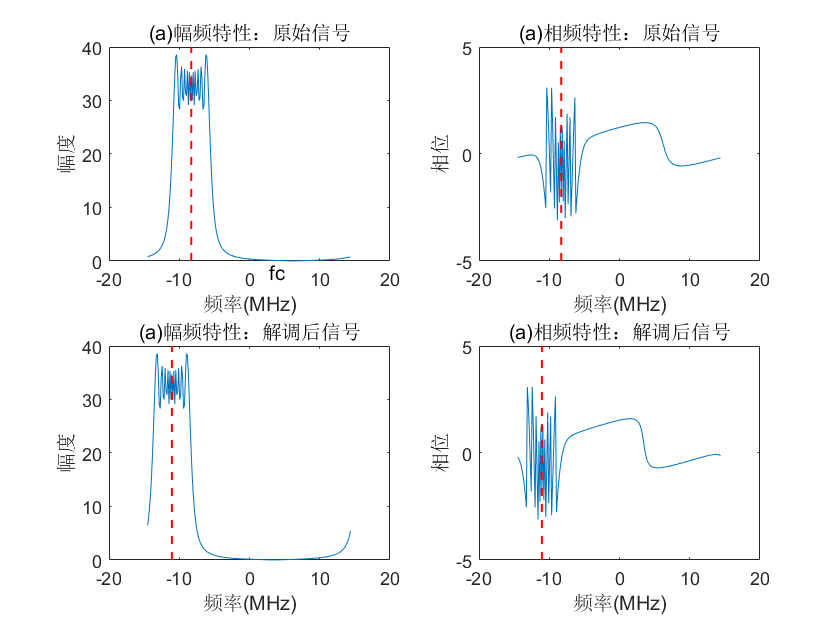

tau =2500/N*T;                                         % 时延tau=3.4476 us
fc_tau = fc-K*tau+(ceil((fc-K*tau)/(-Fs)-1/2))*Fs;     % 时延后的中心频率
fc_jt = -K*tau+(ceil((-K*tau)/(-Fs)-1/2))*Fs;          % 时延后的中心频率

st5 = exp(1i*2*pi*(fc*(t-tau)+1/2*K*(t-tau).^2));      % 原始信号  
st6 = exp(1i*2*pi*(fc*(-tau)+1/2*K*(t-tau).^2));       % 解调后信号

sf5 = fftshift(fft(st5,[],2),2);          
sf6 = fftshift(fft(st6,[],2),2);

figure,set(gcf,'Color','w');
subplot(2,2,1),plot(f*1e-6,abs(sf5));
line([fc_tau*1e-6,fc_tau*1e-6],[0 40],'linestyle','--','Color','r', 'LineWidth', 1);
text(fc*1e-6,-2,'fc')
title('(a)幅频特性：原始信号'),xlabel('频率(MHz)'),ylabel('幅度');
subplot(2,2,2),plot(f*1e-6,angle(sf5));
line([fc_tau*1e-6,fc_tau*1e-6],[-5 5],'linestyle','--','Color','r', 'LineWidth', 1);
title('(a)相频特性：原始信号'),xlabel('频率(MHz)'),ylabel('相位');
subplot(2,2,3),plot(f*1e-6,abs(sf6));
line([fc_jt*1e-6,fc_jt*1e-6],[0 40],'linestyle','--','Color','r', 'LineWidth', 1);
title('(a)幅频特性：解调后信号'),xlabel('频率(MHz)'),ylabel('幅度');
subplot(2,2,4),plot(f*1e-6,angle(sf6));
line([(fc_jt)*1e-6,fc_jt*1e-6],[-5 5],'linestyle','--','Color','r', 'LineWidth', 1);
title('(a)相频特性：解调后信号'),xlabel('频率(MHz)'),ylabel('相位');

## 脉冲压缩 -- 匹配滤波

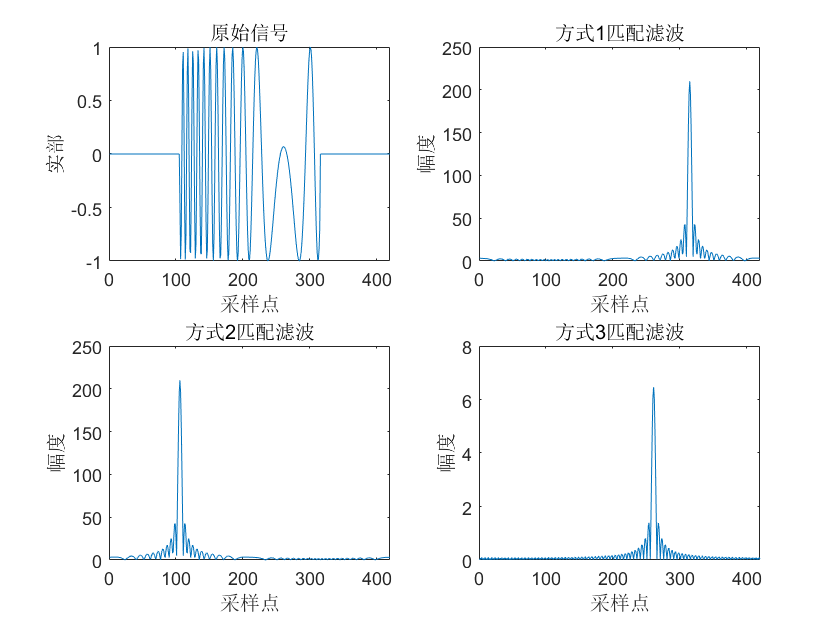

tau =150/N*T;   
st7 = exp(1i*2*pi*(fc*(t-tau)+1/2*K*(t-tau).^2));         % 基本信号
st8 = [zeros(1,N/2),st7,zeros(1,N/2)];                    % 补零信号
Nfft = 2*N; 
f_h = ((0:Nfft-1)-Nfft/2)/Nfft*Fs;

Sf = fftshift(fft(st8,[],2),2);                           % 实际信号的傅里叶变换
Hf1 = fftshift(fft(conj(fliplr(st7)),Nfft,2),2);          % 方式1的匹配滤波器
Hf2 = fftshift(conj(fft(st7,Nfft,2)),2);                  % 方式2的匹配滤波器
Hf3 = exp(1i*pi*f_h.^2/K);                                % 方式3的匹配滤波器

S1 = ifft(ifftshift(Sf.*Hf1,2),[],2);
S2 = ifft(ifftshift(Sf.*Hf2,2),[],2);
S3 = ifft(ifftshift(Sf.*Hf3,2),[],2);

figure,set(gcf,'Color','w');
subplot(2,2,1),plot(real(st8));
title('原始信号'),xlabel('采样点'),ylabel('实部');
subplot(2,2,2),plot(abs(S1));
title('方式1匹配滤波'),xlabel('采样点'),ylabel('幅度');
subplot(2,2,3),plot(abs(S2));
title('方式2匹配滤波'),xlabel('采样点'),ylabel('幅度');
subplot(2,2,4),plot(abs(S3));
title('方式3匹配滤波'),xlabel('采样点'),ylabel('幅度');

## 脉冲压缩--解线性调频

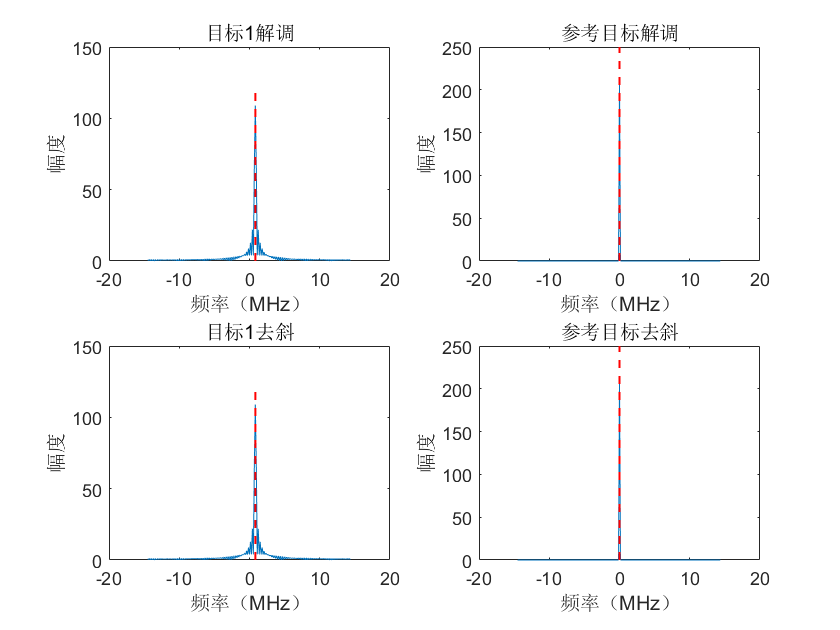

tau =100/N*T;                                                               % 目标1信号时延
tref =130/N*T;                                                              % 参考信号时延（目标1）
fdc1 = -K*(tau-tref);
fdc2 = 0;
st9 = (abs(t-tau)<T/2).*exp(1i*2*pi*(fc*(t-tau)+1/2*K*(t-tau).^2));         % 目标1信号
st10 = exp(1i*2*pi*(fc*(t-tref)+1/2*K*(t-tref).^2));                        % 参考信号
st11 = st9.*conj(st10);                                                     % 目标1差频
st12 = st10.*conj(st10);                                                    % 参考目标差频
Sd1 = fftshift(fft(st11,[],2),2);                                           % 目标1差频频谱                           
Sd2 = fftshift(fft(st12,[],2),2);                                           % 参考目标差频频谱
Hrvp = exp(-1i*pi/K*f.^2);                                                  % 去斜滤波器
Sdc1 = Sd1.*Hrvp;                                                           % 去斜
Sdc2 = Sd2.*Hrvp;                                                           % 去斜
figure,set(gcf,'Color','w');
subplot(2,2,1),plot(f*1e-6,abs(Sd1));
line([fdc1*1e-6,fdc1*1e-6],[0 120],'linestyle','--','Color','r', 'LineWidth', 1)
title('目标1解调'),xlabel('频率（MHz）'),ylabel('幅度');
subplot(2,2,3),plot(f*1e-6,abs(Sdc1));
line([fdc1*1e-6,fdc1*1e-6],[0 120],'linestyle','--','Color','r', 'LineWidth', 1)
title('目标1去斜'),xlabel('频率（MHz）'),ylabel('幅度');
subplot(2,2,2),plot(f*1e-6,abs(Sd2));
line([fdc2*1e-6,fdc2*1e-6],[0 250],'linestyle','--','Color','r', 'LineWidth', 1)
title('参考目标解调'),xlabel('频率（MHz）'),ylabel('幅度');
subplot(2,2,4),plot(f*1e-6,abs(Sdc2));
line([fdc2*1e-6,fdc2*1e-6],[0 250],'linestyle','--','Color','r', 'LineWidth', 1)
title('参考目标去斜'),xlabel('频率（MHz）'),ylabel('幅度');

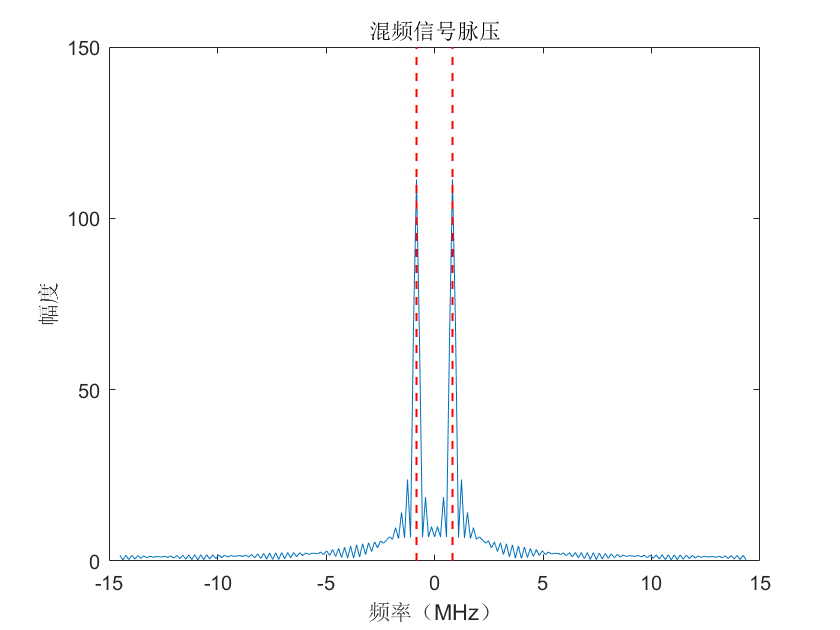


% 多目标混频输出
tau1 =100/N*T;                                                               % 目标1信号时延
tau2 =160/N*T;                                                               % 目标2信号时延
fdc1 = -K*(tau1-tref);
fdc2 = -K*(tau2-tref);

st13 = (abs(t-tau)<T/2).*exp(1i*2*pi*(fc*(t-tau1)+1/2*K*(t-tau1).^2)); 
st14 = (abs(t-tau)<T/2).*exp(1i*2*pi*(fc*(t-tau2)+1/2*K*(t-tau2).^2)); 
st15 = st13+st14;
st16 = st15.*conj(st10); 
sf17 = fftshift(fft(st16,[],2),2);
sf18 = sf17.*Hrvp;
figure,set(gcf,'Color','w');
plot(f*1e-6,abs(sf18));
line([fdc1*1e-6,fdc1*1e-6],[0 150],'linestyle','--','Color','r', 'LineWidth', 1)
line([fdc2*1e-6,fdc2*1e-6],[0 150],'linestyle','--','Color','r', 'LineWidth', 1)
title('混频信号脉压'),xlabel('频率（MHz）'),ylabel('幅度');